e = Data.signals.e;
% a = Data.signals.a;
y = Data.signals.y;
e_max = max(abs(e))

e_max = 0.0094

e_rms = rms_error(e)

e_rms = 0.0035

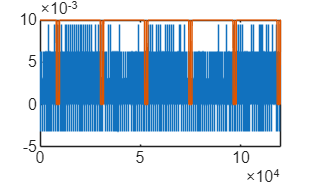

scale = 0.0001;

figure; stairs(e);
hold on;
plot(0.01*(1-sign(abs(a))));

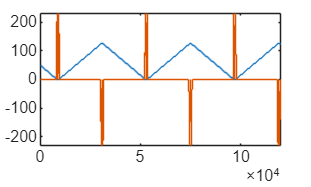

%hold on; stairs(a.*scale);
figure; stairs(y); 
hold on; stairs(a);


Fres = 0.1

Fres = 0.1000

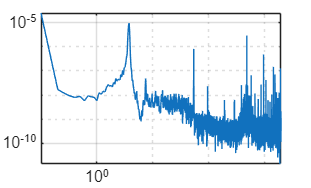

fs = Data.settings.fs;
nfft = fs/Fres;
window = hanning(nfft);
noverlap = floor(nfft/2);
[PSD, f] = pwelch(e,window,noverlap,nfft,fs,"onesided"); %PSD
figure; plot(f,PSD);
yscale log;
xscale log;
grid on;

Trun = 120

Trun = 120

N_samples = Trun*Fs; %measurement size per duration(samples)
T_terminate = 5;
Fres = 0.1

Fres = 0.1000



Exercise = "ProtoLab_setup_45_2410";
Measurement = "Setpoint_11s_13p5Hz";
SampleFreq = "fs_" + Fs + "_Hz";

ModelName = "Hardware_Performance_run";
[success, y,e,a] = StartSignalMeasurement(p,N_samples,T_terminate,ModelName);

Starting the measurement, should take 120 seconds to collect 480000 Samples.
Measurement finished.
Retrieving measurement file(s).
Files retrieved.


if(~success)
    error("No measurement made!");
end
e_max = max(abs(e))

e_max = 0.0094

e_rms = rms_error(e)

e_rms = 0.0035

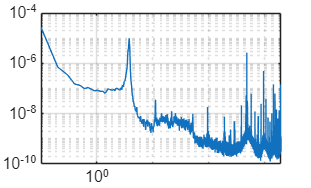


nfft = Fs/Fres;
window = hanning(nfft);
noverlap = floor(nfft/2);
[PSD, f] = pwelch(e,window,noverlap,nfft,fs,"onesided"); %PSD
figure; plot(f,PSD);
yscale log;
xscale log;
grid on;

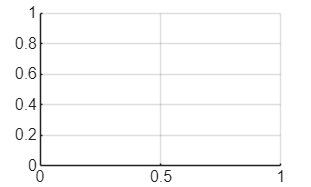


Path = "PerformanceMeasurements/"  ...
        + Exercise ...
        + "/" + SampleFreq;

measurementName = Measurement + "_T" + Trun + "_S" + N_samples;
saveMeasurement(...
struct("runtime", Trun, "fs", Fs, "samples", N_samples), ...%settings    
struct("a", a,"e",e,"y",y), ... %signals
struct("PSD",PSD,"f",f,"e_max",e_max,"e_rms",e_rms),...
Path + '/PerformanceData/'+ measurementName);

figure; hold on; grid on;

n = (1:length(e));
accel_region = (abs(sign(a))).*e_max;
area(n,accel_region*1000 ,'FaceColor',"r",'FaceAlpha',0.4,'EdgeColor','none')

Error using area (line 60)
X must be same length as Y.

area(n,-accel_region*1000 ,'FaceColor',"r",'FaceAlpha',0.4,'EdgeColor','none')
stairs(e);

figure; stairs(y); 
hold on; stairs(a);
grid on;

function e_rms = rms_error(e)
%RMS_ERROR  Compute RMS value of an error signal.
%
%   e_rms = RMS_ERROR(e)
%
%   Inputs:
%       e - error signal vector (difference between ref and measurement)
%
%   Output:
%       e_rms - root mean square error
%
%   Example:
%       e = [0.1, -0.2, 0.05, 0.15];
%       e_rms = rms_error(e)

    % Ensure it's a vector
    e = e(:);

    % Compute discrete-time RMS
    e_rms = sqrt(mean(e.^2));
end
